### Filtro di Sharpening

Un filtro Sharpen è un filtro che accentua i dettagli. 

- Trasforma l'immagine I in un immagine sfocata I2.

- Sottrai I2 da I per ottenere i dettagli I3

- Somma un fattore k all'immagine I3

- Aggiungi i dettagli all'immagine originale I

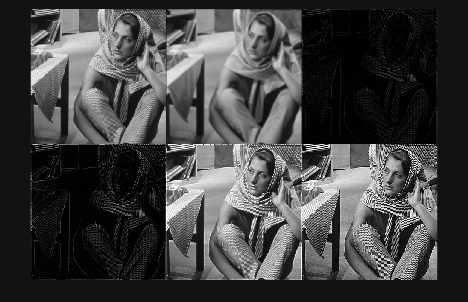

I = rgb2gray(imread("imgs/barbara.png"));

% 1. Applichiamo il filtro passa basso.
I2 = uint8(conv2(I,fspecial("average",7),"same"));

% 2. Otteniamo i dettagli dell'immagine (base)
I3 = I - I2;

% 3. Sommiano un fattore k all'immagine I3
I4 = I3 * 2;

% 4. Aggiungo i dettagli all'immagine originale I
I5 = I + I4;

% È possibile anche usare una funzione di libreria
sharp = imsharpen(I,"Amount",5);

montage({I,I2,I3,I4,I5,sharp});